clear all;close all;

% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\0712_0p.CSV']); %台大1.4m實測

% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1118_27p.CSV']);
% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1119_7p.CSV']); % power sensor at coil close to center
mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1127_0p.CSV']);

% mo0=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_0P.CSV']);
% mo1=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_1P.CSV']);
% mo2=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_2P.CSV']);
% mo3=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_3P.CSV']);
% mo4=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_4P.CSV']);
% mo5=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_5P.CSV']);
% mo6=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_6P.CSV']);
% mo7=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_7P.CSV']);
% mo8=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1120_8P.CSV']);

% mo=[mo0;mo1;mo2;mo3;mo4;mo5;mo6;mo7;mo8];


moo=mo;
% mo=moo(:,[1:17]);
% mo(1,:)=[];

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
t=mo(:,1);

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

m = mo(:,3:5); %%%% to guess
acc1 = mo(:,6:8);  %無校正
% gyr1=mo(:,9:11);
tem=moo(:,9);
f=moo(:,10);
ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
% aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
% GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2)*0.01;
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

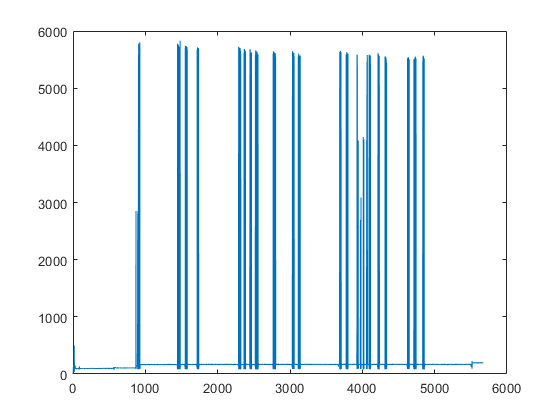

close all
% figure(1)
% plot(t,smooth(GG,200))
% 
figure(2)
plot(t,mm4)

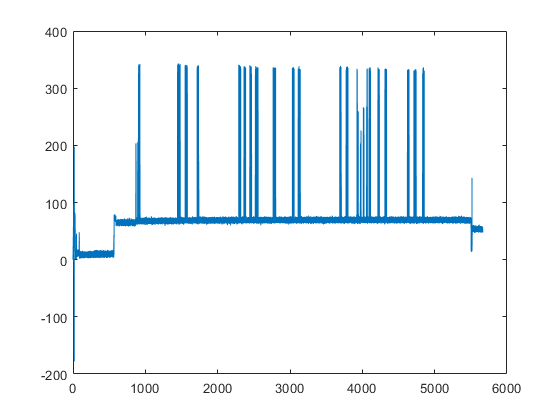


% figure(3)
% % plot(t,m)
% hold on
% plot(t,m(:,1)-500)
% plot(t,m(:,2)-100)
% plot(t,m(:,3)+500)
% hold off

figure(4)
plot(t,m(:,1))

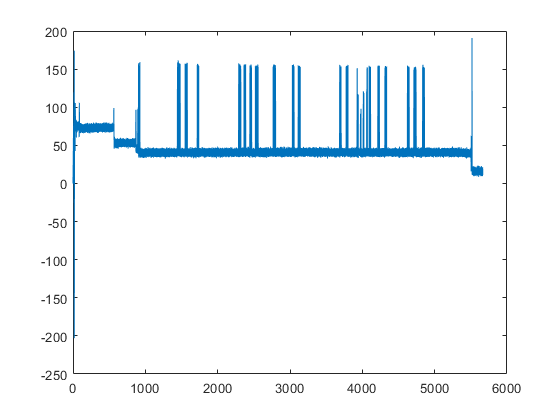

figure(5)
plot(t,m(:,2))

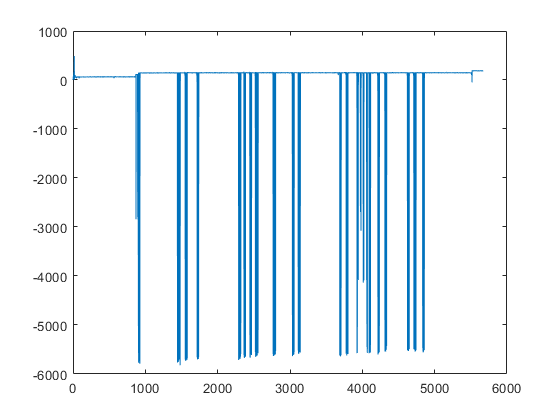

figure(6)
plot(t,m(:,3))

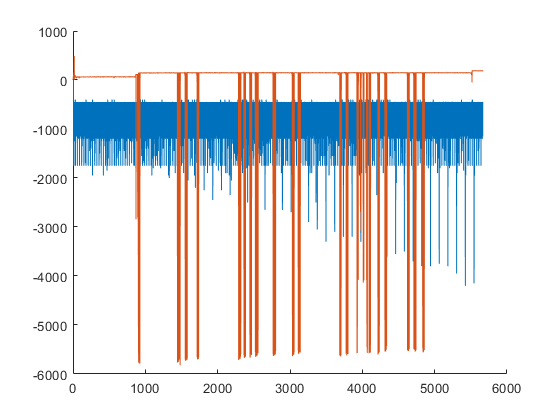

%power check dt
close all;

dt=[];dt(a1,1)=zeros;
for i=2:a1
    dt(i)=t(i)-t(i-1);
end
dt(2)=0;


hold on
% plot(t,dt)
plot(t,dt*-50000)
plot(t,m(:,3))
hold off